clear
clc

A = [2/3 1/3 0; 1/3 4/3 1/3; 0 1/3 2/3]*(pi/4)

A =     0.5236    0.2618         0
    0.2618    1.0472    0.2618
         0    0.2618    0.5236


B = [(-2+pi)/pi; 4/pi; (-2+pi)/pi]

B =     0.3634
    1.2732
    0.3634


sol = A\B

sol =     0.1148
    1.1585
    0.1148


Plot

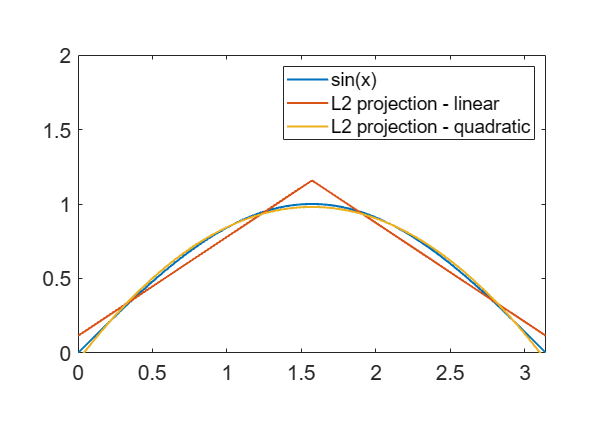

% plot 1
x=0:0.01:pi;
plot(x,sin(x),'DisplayName','sin(x)',LineWidth=1.5)
hold on

% % plot 2
% a = pi/2
% y = x - x.^3/factorial(3) + x.^5/factorial(5) - x.^7/factorial(7) + x.^9/factorial(9);
% y = sin(a) + (cos(a)).*(x-a) + (-sin(a)).*((x-a).^2)/factorial(2);
% plot(x,y,'--','DisplayName','Taylor series (a=\pi/2) - 3 terms',LineWidth=1.5)
% 
% % plot 3
% y = [];
% for i=x
%     if i<pi/2
%         y = [y; ((pi/2-i)/(pi/2))*0+((2*i)/(pi))*1];
%     else
%         y = [y; ((pi-i)/(pi/2))*1+((pi/2-i)/(-pi/2))*0];
%     end
% end
% plot(x,y,'--','DisplayName','Linear piecewise interpolation',LineWidth=1.5)
% 
% % plot 4
% y = (((0-x).*(pi-x))/((0-pi/2)*(pi-pi/2)))*1;
% plot(x,y,'--','DisplayName','Quadratic lagrange interpolation',LineWidth=1.5)

% plot 5
y = [];
for i=x
    if i<pi/2
        y = [y; ((pi/2-i)/(pi/2))*sol(1)+((2*i)/(pi))*sol(2)];
    else
        y = [y; ((pi-i)/(pi/2))*sol(2)+((pi/2-i)/(-pi/2))*sol(3)];
    end
end
plot(x,y,'DisplayName','L2 projection - linear',LineWidth=1.5)

% plot 6
y = -0.050465 + 1.31224.*x - 0.417697.*x.^2;
plot(x,y,'DisplayName','L2 projection - quadratic',LineWidth=1.5)


xlim([0,pi])
ylim([0,2])
daspect([1 1 1])
legend
set(gcf,'units','pixels','position',[100 100 1000 700]);
set(gca,'FontSize',15);